# Curve Fitting of Covid-19 incidence in Germany with the SIR Model

Mathematical models cannot simulate real-world phenomena in a flawless way. However, they provide a useful approximation of the actual dynamics. To do this, a model is fitted to the real data with a method known as **curve fitting**. The purpose of this practice lies in finding the optimal parameters of the model that can explain relity with the least possible error.

In this script, the data on the incidence of SARS-Covid-19 in Germany from 1st January 2020 up to date is fitted through the algorithm *lsqnonlin, from which the* optimal parameters are deduced from the regression.

(Source: https://www.destatis.de/DE/Home/_inhalt.html)

## Import daily incidence data from spreadsheet

opts = spreadsheetImportOptions("NumVariables", 3);

% Specify sheet and range
opts.Sheet = "Daten";
opts.DataRange = "B6:D530";

% Specify column names and types
opts.VariableNames = ["Date", "Cases", "Deaths"];
opts.VariableTypes = ["string", "double", "double"];

% Import the data
myCovid = readtable("Covid_in_Germany.xlsx", opts, "UseExcel", false)

myCovid = 525×3 table
      Date       Cases    Deaths
    _________    _____    ______

    "28. Jan"      1       NaN  
    "29. Jan"      3       NaN  
    "30. Jan"      0       NaN  
    "31. Jan"      2       NaN  
    "01. Feb"      1       NaN  
    "02. Feb"      3       NaN  
    "03. Feb"      0       NaN  
    "04. Feb"      2       NaN  
    "05. Feb"      0       NaN  
    "06. Feb"      1       NaN  
    "07. Feb"      0       NaN  
    "08. Feb"      1       NaN  
    "09. Feb"      0       NaN  
    "10. Feb"      0       NaN  
    "11. Feb"      0       NaN  
    "12. Feb"      2       NaN  


clear opts

## Store data in a usable format

myDate = myCovid.Date;
myTime = [1:525]';

myCase = table2array(myCovid(:, 2));
myDeath = table2array(myCovid(42:end, 3));

## Visualise  disease dynamics over time

To start off the analysis, it is convenient to visualise the incidence of the disease as a function of time. As a result, we see that the infections can be grouped into three separate curves along with their respective peak. This means that three curve fittings are to be carried out, so that the model can detect the pattern of each and every curve and assign them the correct parameters.

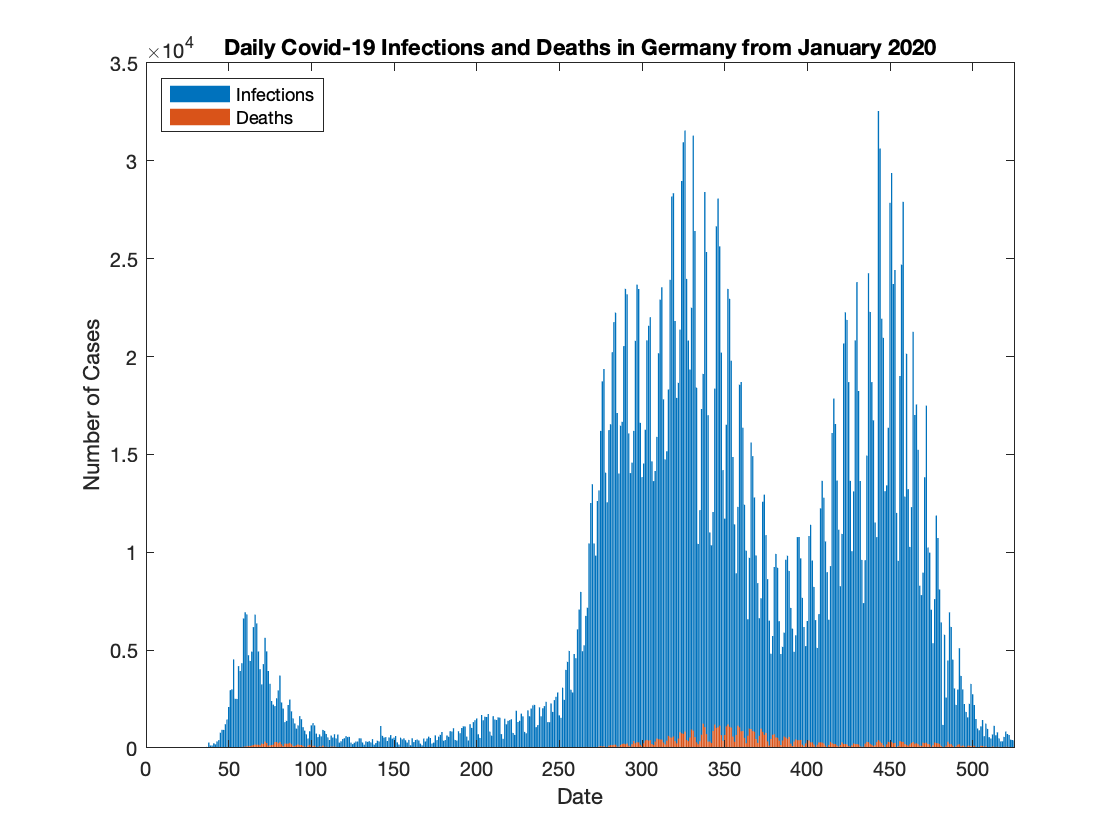

bar(myTime, myCase)
hold on

bar(myTime(42:end), myDeath)

title('Daily Covid-19 Infections and Deaths in Germany from January 2020')

xlabel('Date')
ylabel('Number of Cases')


xlim([0 525])
% xticklabels(myDate)

legend('Infections', 'Deaths', 'Location', 'northwest')
hold off

## Fit SIR model to real data

What is needed for the fitting is a pair of functions: *SIRmodel*, which is passed to *ode45 to *numerically solve the curve given a set of parameters, and SIRerror, which evaluates the mean square error between the solution of *ode45* and the real values of the curve (stored as *myData*). When the latter function is inserted in the algorithm *lsqnonlin*, it returns the optimal values for the parameters to be fitted. In this example, the infection rate $\beta$, the recovery rate $\gamma$ and the initial numer of infected are optimised.

**Normalise to a population size of 10000:**

global N myData myRange
global beta gamma Lambda

Nreal = 83783942;
N = 10000;
norm_case = myCase / Nreal * 10000;

myData = [myTime, myCase];

**First curve:**

myRange = 30:130;

p = 0.1;  % infection probability 
c = 5;    % contact rate

beta = p * c / N;
gamma = 0.2;
I0 = myCase(myRange(1));
Lambda = 11.3

Lambda = 11.3000


X0 = [beta, gamma, I0, Lambda];

X = lsqnonlin(@MSIRerror, X0);


Solver stopped prematurely.

lsqnonlin stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 4.000000e+02.



beta = X(1);
gamma = X(2);
I0 = X(3);
Lambda = X(4)

Lambda = 21.2950

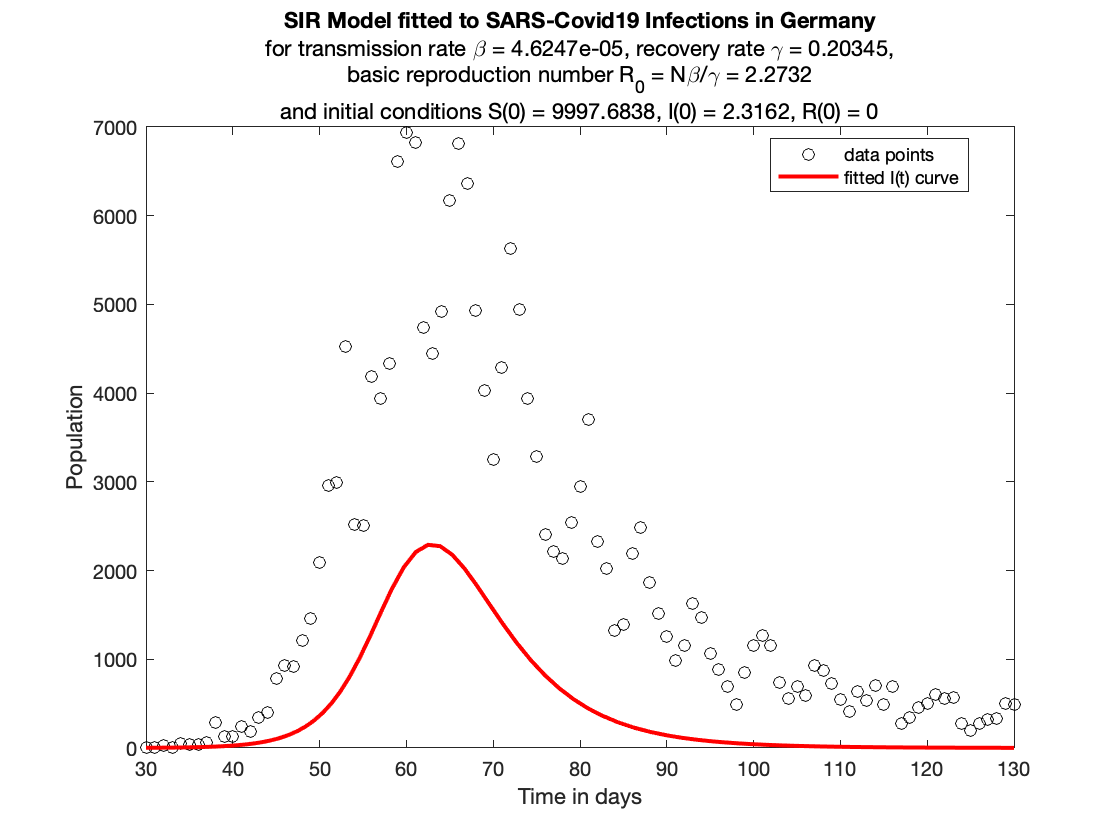


R_0 = beta * N / gamma;

plot(myData(myRange, 1), smmyData(myRange, 2), 'ko')
hold on

tSpan = [myData(myRange(1), 1), myData(myRange(end), 1)];
Y0 = [1000, N - I0 - 1000, I0, 0];

[tSol, YSol] = ode45(@MSIRmodel, tSpan, Y0);

% plot(tSol, YSol(:, 1), 'y')
% plot(tSol, YSol(:, 2), 'b')
plot(tSol, YSol(:, 3), 'r', 'Linewidth', 2)
% plot(tSol, YSol(:, 3), 'g')

title('SIR Model fitted to SARS-Covid19 Infections in Germany')
subtitle({['for transmission rate \beta = ',num2str(beta),', recovery rate \gamma = ',num2str(gamma),','], ...
['basic reproduction number R_0 = N\beta/\gamma = ',num2str(R_0)], ...
    ['and initial conditions S(0) = ',num2str(N - I0),', I(0) = ',num2str(I0),', R(0) = ',num2str(0)]})

xlabel('Time in days')
ylabel('Population')

xlim([myData(myRange(1), 1), myData(myRange(end), 1)])
legend('data points', 'fitted I(t) curve', 'Location', 'best')
hold off

**Second curve:**

myRange = 170:230;

p = 0.1;  % infection probability 
c = 5;    % contact rate

beta = p * c / N

beta = 5.0000e-05

gamma = 0.2

gamma = 0.2000

I0 = myCase(myRange(1))

I0 = 486

Lambda = 11.3

Lambda = 11.3000


X0 = [beta, gamma, I0, Lambda];

X = lsqnonlin(@MSIRerror, X0);


Solver stopped prematurely.

lsqnonlin stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 4.000000e+02.



beta = X(1);
gamma = X(2);
I0 = X(3);
Lambda = X(4)

Lambda = 41.2030

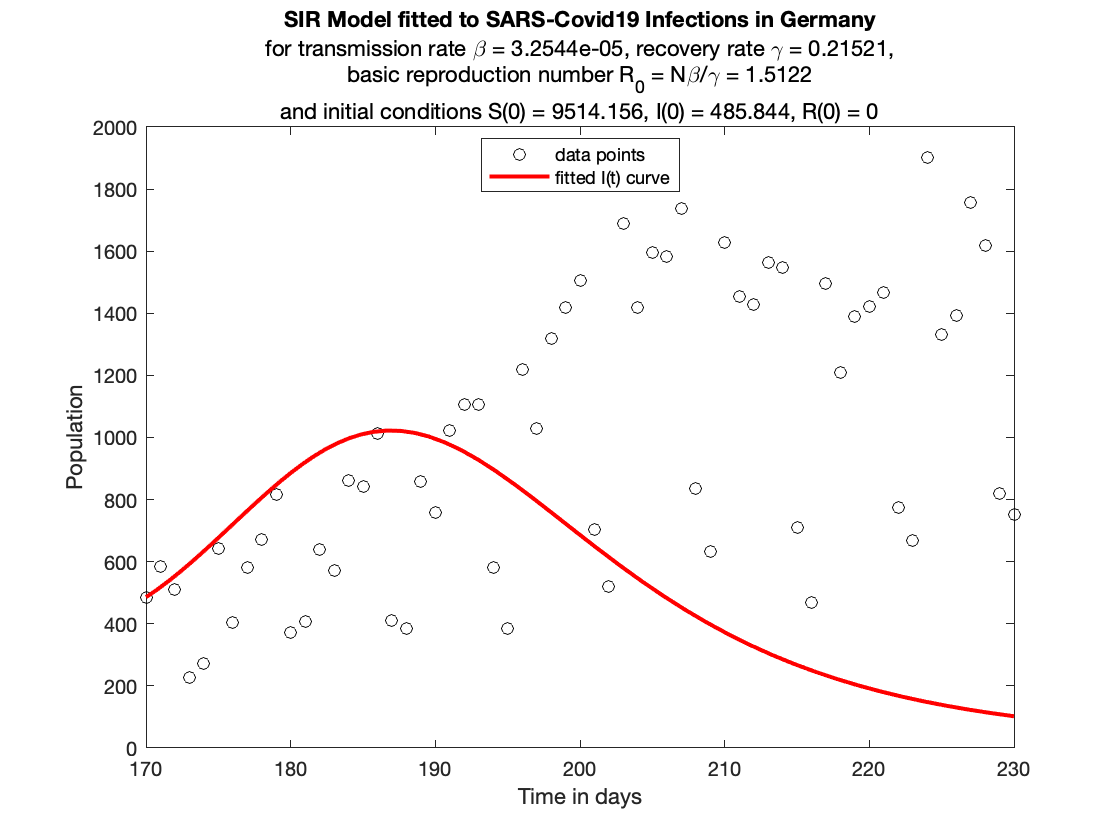


R_0 = beta * N / gamma;

plot(myData(myRange, 1), myData(myRange, 2), 'ko')
hold on

tSpan = [myData(myRange(1), 1), myData(myRange(end), 1)];
Y0 = [1000, N - I0 - 1000, I0, 0];

[tSol, YSol] = ode45(@MSIRmodel, tSpan, Y0);

% plot(tSol, YSol(:, 1), 'y')
% plot(tSol, YSol(:, 2), 'b')
plot(tSol, YSol(:, 3), 'r', 'Linewidth', 2)
% plot(tSol, YSol(:, 3), 'g')

title('SIR Model fitted to SARS-Covid19 Infections in Germany')
subtitle({['for transmission rate \beta = ',num2str(beta),', recovery rate \gamma = ',num2str(gamma),','], ...
['basic reproduction number R_0 = N\beta/\gamma = ',num2str(R_0)], ...
    ['and initial conditions S(0) = ',num2str(N - I0),', I(0) = ',num2str(I0),', R(0) = ',num2str(0)]})

xlabel('Time in days')
ylabel('Population')

xlim([myData(myRange(1), 1), myData(myRange(end), 1)])
legend('data points', 'fitted I(t) curve', 'Location', 'best')
hold off

**Third curve:**

The SIR model failed to adapt to the dynamics of the third curve of infections. This might be due to an overly complex infection pattern and a high level of disturbance which cannot be represented with a simple description such as the SIR model. Variants of the SIR model should be considered to determine a more satisfactory fitting.

myRange = 400:500;

p = 0.1;  % infection probability 
c = 5;    % contact rate

beta = p * c / N

beta = 5.0000e-05

gamma = 0.1

gamma = 0.1000

I0 = myCase(myRange(1))

I0 = 6492

Lambda = 11.3

Lambda = 11.3000


X0 = [beta, gamma, I0, Lambda];

X = lsqnonlin(@MSIRerror, X0);


Solver stopped prematurely.

lsqnonlin stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 4.000000e+02.



beta = X(1);
gamma = X(2);
I0 = X(3);
Lambda = X(4)

Lambda = 11.3000

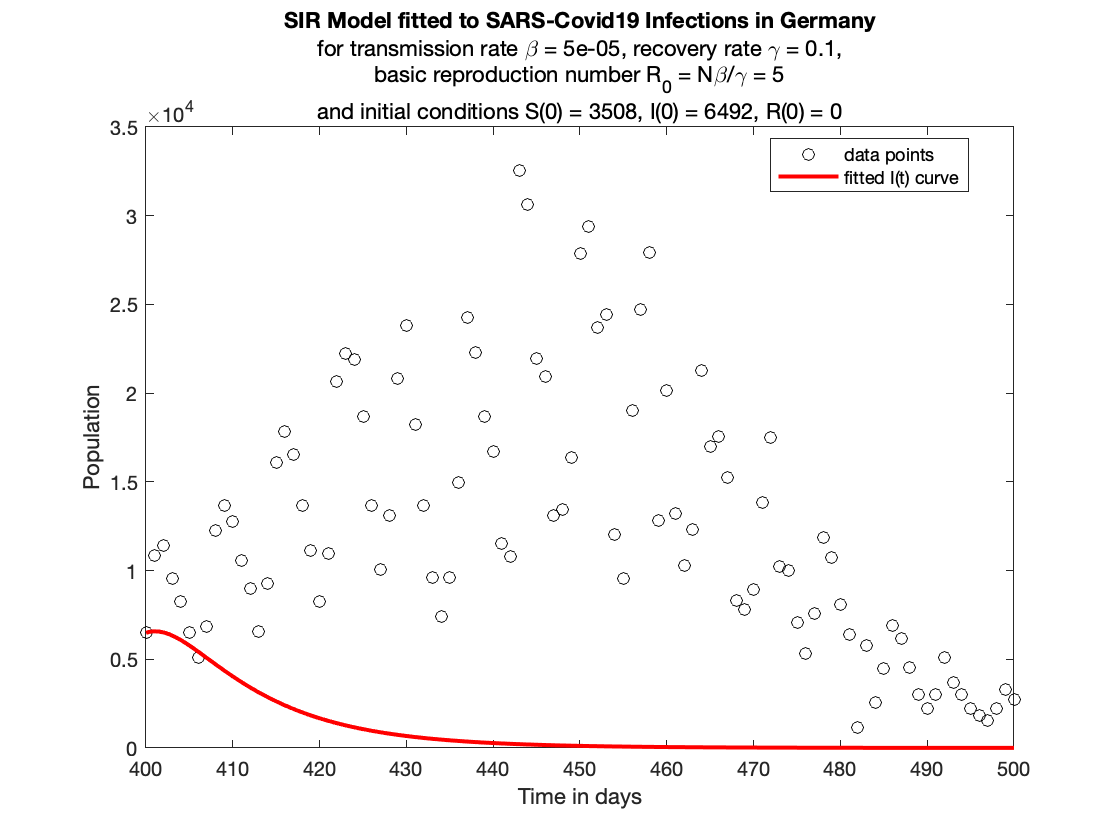


R_0 = beta * N / gamma;

plot(myData(myRange, 1), myData(myRange, 2), 'ko')
hold on

tSpan = [myData(myRange(1), 1), myData(myRange(end), 1)];
Y0 = [1000, N - I0 - 1000, I0, 0];

[tSol, YSol] = ode45(@MSIRmodel, tSpan, Y0);

% plot(tSol, YSol(:, 1), 'y')
% plot(tSol, YSol(:, 2), 'b')
plot(tSol, YSol(:, 3), 'r', 'Linewidth', 2)
% plot(tSol, YSol(:, 3), 'g')

title('SIR Model fitted to SARS-Covid19 Infections in Germany')
subtitle({['for transmission rate \beta = ',num2str(beta),', recovery rate \gamma = ',num2str(gamma),','], ...
['basic reproduction number R_0 = N\beta/\gamma = ',num2str(R_0)], ...
    ['and initial conditions S(0) = ',num2str(N - I0),', I(0) = ',num2str(I0),', R(0) = ',num2str(0)]})

xlabel('Time in days')
ylabel('Population')

xlim([myData(myRange(1), 1), myData(myRange(end), 1)])
legend('data points', 'fitted I(t) curve', 'Location', 'best')
hold off

**Model Function:**

function dYdt = MSIRmodel(~, Y)

    global beta gamma Lambda
    
    delta = 0.1;
    
    % Extract M, S, I, and R from input vector Y
    M = Y(1); % immune from birth
    S = Y(2); % susceptible
    I = Y(3); % infected
    R = Y(4); % recovered
    
    % Define dMdt, dSdt, dIdt, dRdt from the ODEs
    dMdt = Lambda - delta * M;
    dSdt = -beta * S * I + delta * M;
    dIdt = beta * S * I - gamma * I;
    dRdt = gamma * I;

    % Create output column vector dYdt
    dYdt = [dMdt; dSdt; dIdt; dRdt];
    
end

**Fit Function:**

function SSR = MSIRerror(X)

    global N myData myRange
    global beta gamma Lambda
    
    beta = X(1);
    gamma = X(2);
    I0 = X(3);
    Lambda = X(4);
    
    tSpan = myRange;
    Y0 = [1000, N - I0 - 1000, I0, 0];
    
    [~, YSol] = ode45(@MSIRmodel, tSpan, Y0);
    
    SSR = smooth(myData(myRange, 2)) - YSol(:, 3);
    
end